# Exploring autocorrelation

#### Outstanding questions:

 - I can't get es2true and es_w_true from V to match. Is this a problem? Why not?

- The filter function with autocorrelation in b seems to be doing the right thing to generate data, but gives opposite ar estimates.  The inverse filter seems to "unsmooth" the data but gives the right ar estimates. Seems backwards.

- Also, when do you use a symmetrical filter vs. asymmetrical

### Demo: Show the functional form of several kinds of correlated error matrices (V)

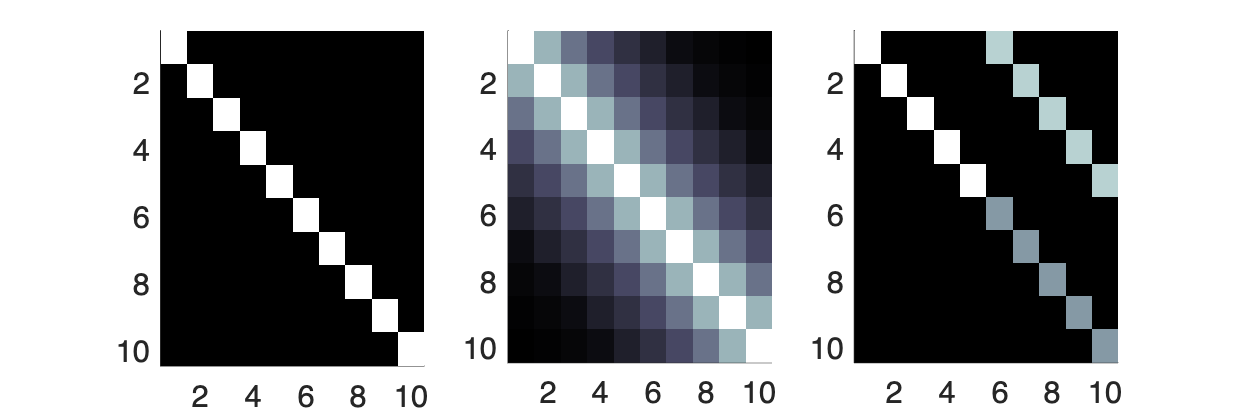

create_figure('cov e', 1, 3);
colormap bone;

X = eye(10); imagesc(X); set(gca, 'YDir', 'reverse'); axis tight

% time series

subplot(1, 3, 2); set(gca, 'YDir', 'reverse'); axis tight
rho = .7; 
X = toeplitz([1 rho rho^2 rho^3 rho^4 rho^5 rho^7 rho^8 rho^9 rho^10]);
imagesc(X);

% subject series
subplot(1, 3, 3); set(gca, 'YDir', 'reverse'); axis tight
rho = .7; k = .4;
X = diag([1 1 1 1 1 .6 .6 .6 .6 .6]);
X = X + diag([.8 .8 .8 .8 .8], 5);
imagesc(X);

#### Create autocorrelation and whitening matrices

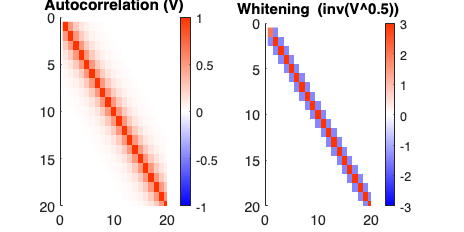

n = 100;    % number of time points

rho = 0.5;  % rho autocorrelation param for AR(1) model 

[V, v_vec] = generate_V_ar1

% e(i+1) = rho * e(i) + eta(i), e = error, eta = innovation/new random error

v_vec = 1;

for i = 2:n 

    v_vec(i) = rho .^ (i-1); 

end

V = toeplitz(v_vec);
create_figure('V', 1, 2);
imagesc(V); colorbar
title('Autocorrelation (V)')
set(gca, 'YDir', 'Reverse'); axis tight
% zoom in
set(gca, 'XLim', [0 20], 'YLim', [0 20])
canlab_redblue_symmetric_colormap

subplot(1, 2, 2)
imagesc(inv(V .^ 0.5))
title('Whitening (inv(V\^0.5))')
colorbar
set(gca, 'YDir', 'Reverse'); axis tight
% zoom in
set(gca, 'XLim', [0 20], 'YLim', [0 20])
canlab_redblue_symmetric_colormap

In SPM, you can do it this way:

#### Generate noise with known AR(1) filter

There are several ways of doing this:

- Manual calculation

- Digital filter with a rational transfer function

- Filtering matrix

eta = randn(n, 1); % some data, the ideal whitened error timeseries.  where \epsilon(t) ~ N(0,\sigma^2) 
create_figure('e'); 
plot(eta, 'k', 'LineWidth', 2)

% manual generation: e(t) = \rho e(t-1) + \eta(t)
es = eta(1);
for i = 2:length(eta)
    es(i, 1) = rho * es(i - 1) + eta(i);
end

% formulation in aryule is reversed
%es(i) + rho * es(i - 1) = eta

% sigma^2 / (1 - rho.^2)  is scaling factor, times V

K = inv(V ^ 0.5); % whitening matrix
K' * V * K % identity matrix, whitened autocorr
figure; plot(eta, 'k'); hold on; plot(K * es)

% filter.m
% - results are slightly different, but close
% - To use the filter function with the b coefficients from an FIR filter, use y = filter(b,1,x)
% - For moving average of past 5 elements, b = [1 1 1 1 1]/n
es2 = filter([1 rho], 1, eta);
corr(es, es2)

ans = 0.9701


% NOTE: docs on aryule.m say we need to do it this way to generate ar(1)
% time series:
% y = filter(1, [1 rho], eta);
% then, arcoeffs = aryule(y, 1)
% and this works to recover the true rho pretty well. 
% BUT this does not look like a smooth time series, it looks like the
% opposy xite. 
% Compare these:
% y = filter(1, [1 1], eta);
% figure; plot(eta); hold on; plot(y)
% y = filter([1 1], 1, eta);
% figure; plot(eta); hold on; plot(y)


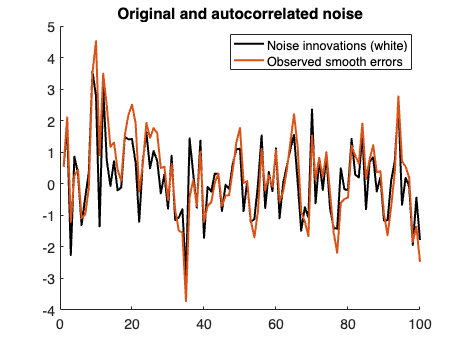

hold on; 
plot(es, 'LineWidth', 2)
legend({'Noise innovations (white)' 'Observed smooth errors'})
title('Original and autocorrelated noise')

### Calculate whitened time series with ideal (true) coefficients

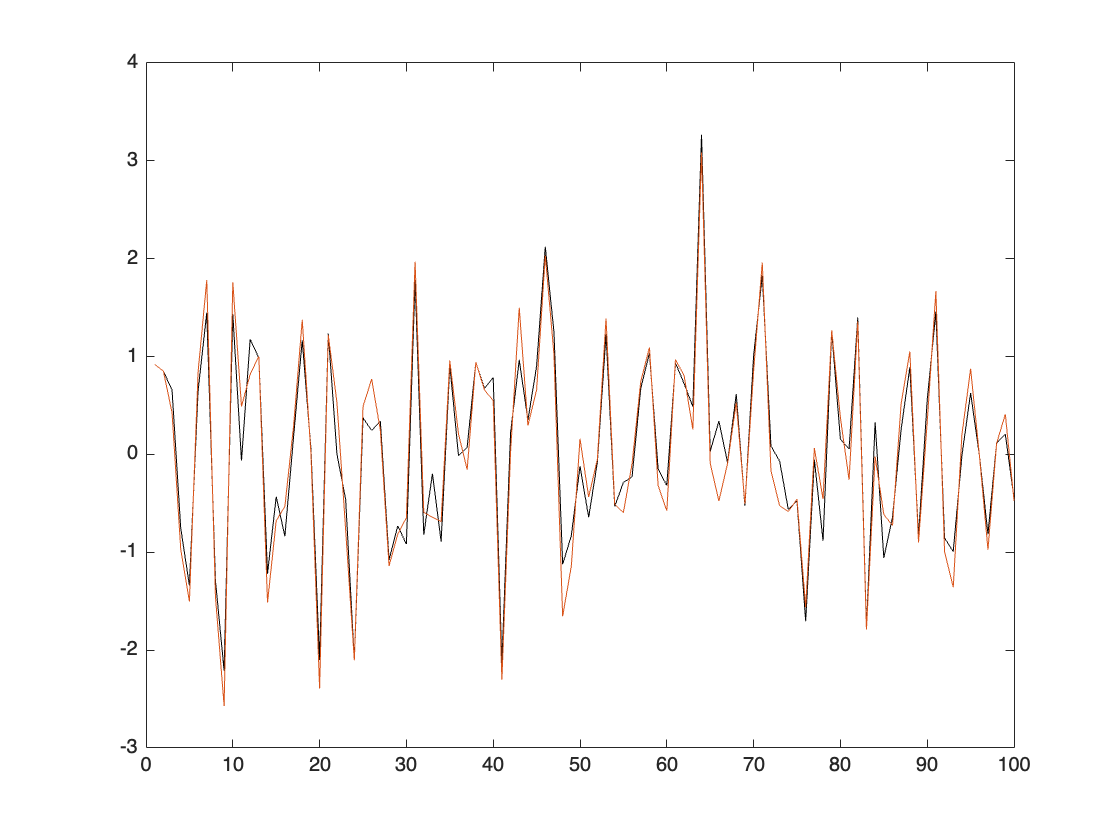

% see:
% https://online.stat.psu.edu/stat462/node/189/
% - Durbin-Watson test and others
% - Cochrate-Orcutt procedure and others

% Filtering is not exactly invertible, but close
es2inv = filter([1 -rho], 1, es2);
figure; plot(eta, 'k'); hold on; plot(es2inv)

corr(eta, es2inv)

ans = 0.9728

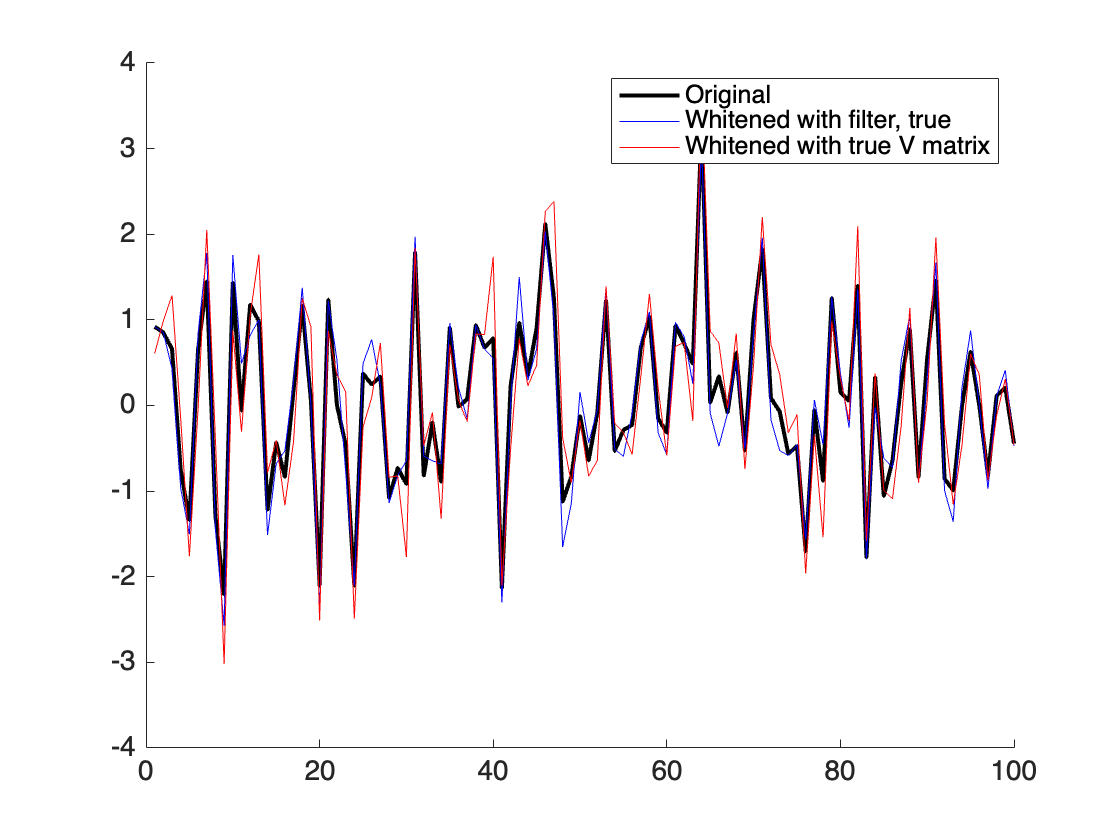


create_figure('e2');

plot(eta, 'k', 'LineWidth', 2) 

% plot(inv(sqrt(V)) * es, 'r', 'LineWidth', 2) % ideal whitened with true V matrix

es_w_true = inv(V ^ 0.5) * es;  % Whitened with true V matrix filter
% Note: sqrt(V) is different than V ^ 0.5 here. sqrt() is element-wise, not matrix square root

plot(es2inv, 'b')
plot(es_w_true, 'r') % ideal whitened with true V matrix
legend({'Original' 'Whitened with filter, true' 'Whitened with true V matrix'})

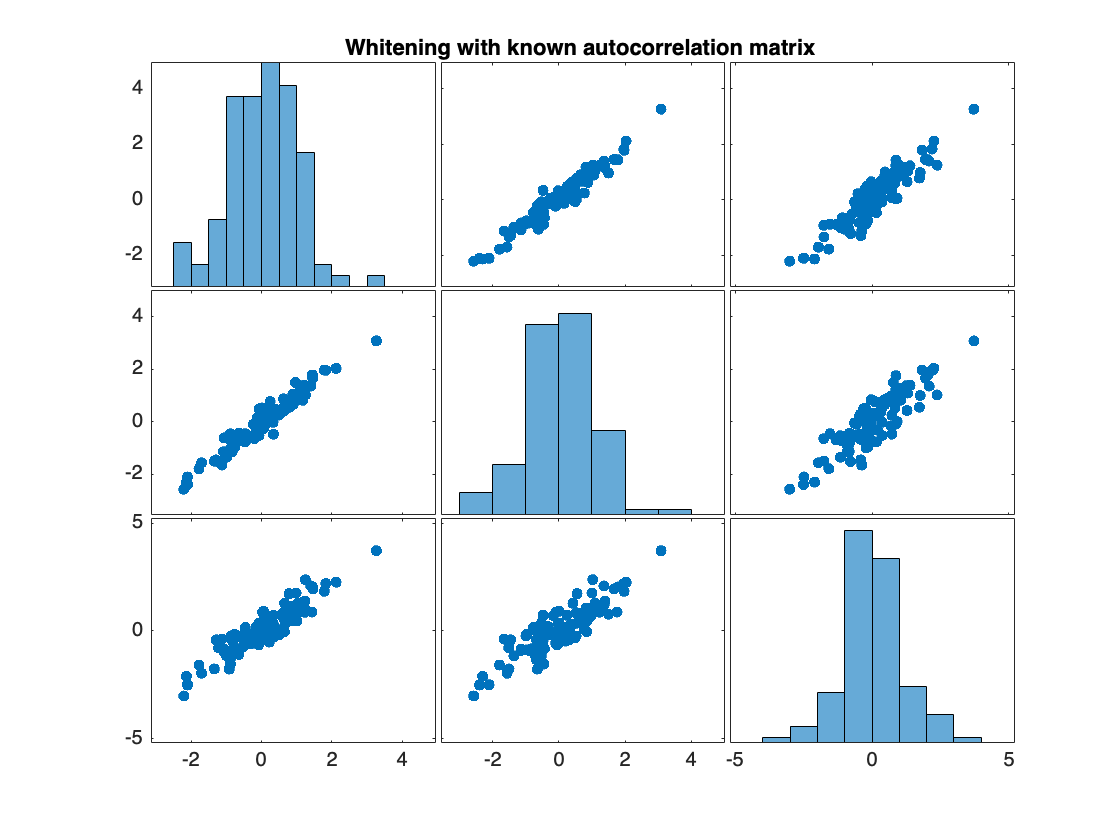


figure; plotmatrix([eta es2inv es_w_true])
title('Whitening with known autocorrelation matrix')

### Estimate filter coefficients from data and whitened time series

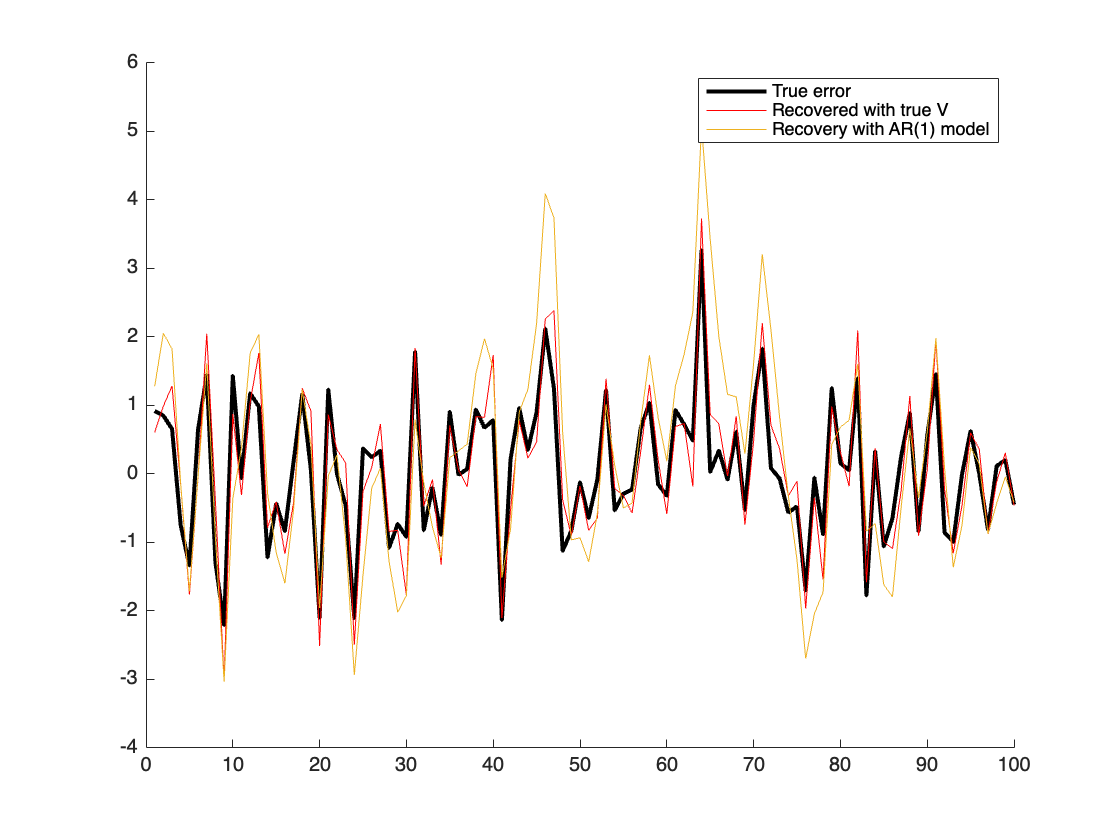

% with noisy V estimate based on data - can we recover the true
% coefficient?
rho_hat = aryule(es, 1);

v_hat_vec = rho_hat(1);

for i = 2:n 

    v_hat_vec(i) = rho_hat(2) .^ (i-1); 

end
V_hat = toeplitz(v_hat_vec);

es_w_aryule = inv(V_hat ^ 0.5) * es;  % Whitened with matrix filter

figure; hold on;
plot(eta, 'k', 'LineWidth', 2) 
plot(es_w_true, 'r') % ideal whitened with true V matrix
plot(es_w_aryule) % recovered: whitened with estimated V matrix

legend({'True error' 'Recovered with true V' 'Recovery with AR(1) model'})


correlation_to_text([eta es2inv es_w_true es_w_aryule], [], {'eta' 'es2inv' 'es_w_true' 'es_w_aryule'});

Crit=0.20	eta	es2inv	es_w_true	es_w_aryule	
eta	1.000	0.973*	0.926*	0.788*	
es2inv	0.973*	1.000	0.878*	0.711*	
es_w_true	0.926*	0.878*	1.000	0.858*	
es_w_aryule	0.788*	0.711*	0.858*	1.000	



% see also:
%[xc,Vi] = canonical_autocorrelation(TR,n,varargin)


### Plot PSD and autocorrelation of timeseries

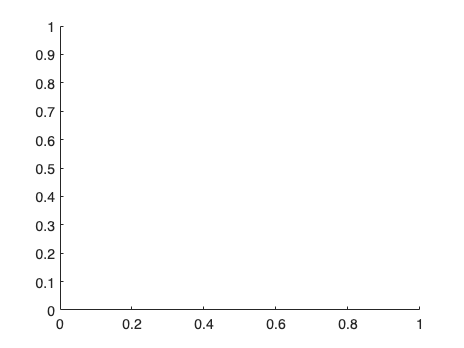

n = 100;    % number of time points

%  y = noise_arp(n, rho);

eta = randn(n, 1); % some data, the ideal whitened error timeseries.  where \epsilon(t) ~ N(0,\sigma^2) 

% manual generation: e(t) = \rho e(t-1) + \eta(t)
es = eta(1);
y = zeros(n, 1);
for i = 2:length(eta)
    y(i, 1) = rho * y(i - 1) + eta(i);
end

% Autocorrelation function

[C, lags] = xcorr(y, 16, 'normalized');
C = C(lags >= 0);
lags = lags(lags >= 0);
create_figure('acf'); 

plot(lags, C, 'bo-', 'LineWidth', 2, 'MarkerFaceColor', [.5 .5 .5]); xlabel('Lag'); ylabel('Correlation');

hold on; plot(0:15, V(1, 1:16), 'k')

create_figure('fftplot');
[myfft, freq, handle] = fft_plot_scnlab(y, 1);

% different
[Pxx,F] = periodogram(y);
plot(F, Pxx);

figure; plot(myfft, Pxx(1:5000), 'ko');
corr(myfft, Pxx(1:5000))



A = [1 -rho];

y = filter(1, A, eta);

arcoeffs = aryule(y,2)



[C, lags] = xcorr(y, 16, 'normalized');
C = C(lags >= 0);
lags = lags(lags >= 0);
create_figure('acf'); 
plot(lags, C, 'ko-', 'LineWidth', 2, 'MarkerFaceColor', [.5 .5 .5]); xlabel('Lag'); ylabel('Correlation');


